# **UDP - Loopback**

This example demonstrates how one Real-Time UDP Client and one Real-Time UDP Server communicate.

All UDP nodes are located in the same system and on the same Ethernet interface. This is achieved by assigning multiple alias-IP addresses to one Ethernet interface. With this setup, the UDP Client and Server are on the same physical Ethernet interface.

The Simulink model features the Real-Time UDP blocks from the [speedgoatlib_IO71X](matlab:open('https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io70x_io71x_io79x.html')) library.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with at least one unused Ethernet interface

### Wiring of Target Machine

No physical wiring is required.

### Ethernet Configuration of the Client and Server

Use the **Speedgoat Ethernet Configuration Tool** to assign the IP address to one unused Ethernet interface (on-board or IO71x/IO79x) on the target machine. The communication between the client and the server(s) on the unused Ethernet interface is performed over the localhost. No cable is required.

The IP address assigned should be 192.168.10.1. The netmask for this local address is 255.255.255.0. This IP is used as the gateway address for the client and server(s) in this example.

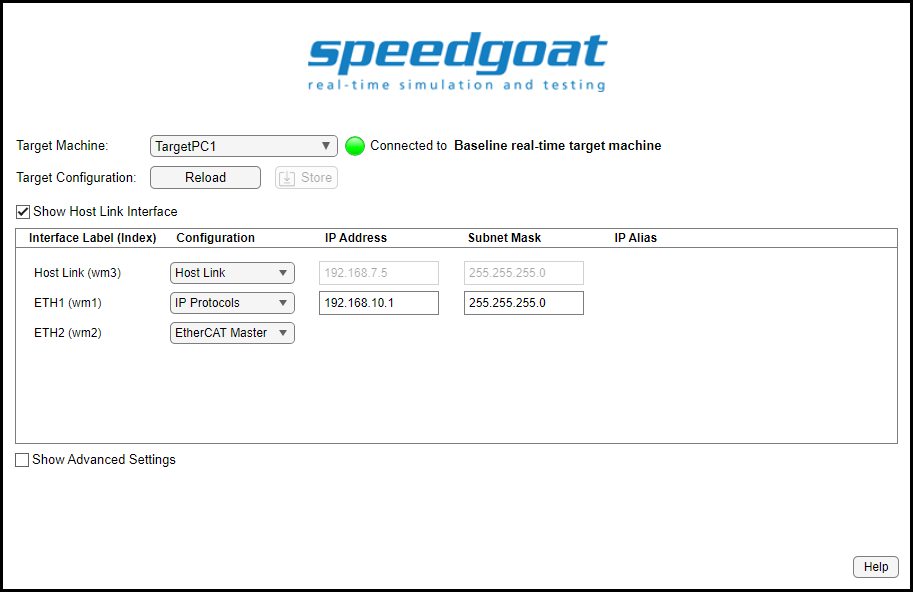

 
% Create target object and connect to target machine
tg = slrealtime;
tg.connect

% Configure the Ethernet interface for the ModbusTCP example
speedgoat.configureEthernet; % Open the Speedgoat Ethernet Configuration tool

Add the IP addresses of the client and server to the same Ethernet interface. Adapt the name of the interface according to your target machine configuration.

 
IP_Sender_00 = '192.168.10.10';
IP_Receiver_00 = '192.168.10.20';

InterfaceName = 'ETH1'; % Ethernet Interface on the target machine used for the example. Adapt this according to your target machine.
ipAliasObj = speedgoat.IpAliasConfiguration('TargetObject', tg);
ipAliasObj.add(InterfaceName, {IP_Sender_00,IP_Receiver_00});

Check the server Ethernet settings:

ipAliasObj.show();

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_UDP_Loopback';
open_system(modelName);

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download the real-time application to the target machine and set stop time
tg.load(modelName);
tg.setStopTime(5);

% Start the real-time application and open the SDI-Viewer
tg.start;

%% Setup SDI to visualize signals
% Get and configure SDI Run
allIDs = Simulink.sdi.getAllRunIDs;
runID1 = allIDs(end);
SDIRun = Simulink.sdi.getRun(runID1);
SDIRun.name = 'Real-Time Simulation';

% Clear and configure plot layout
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(1, 1); % layout with two plots
Simulink.sdi.setSubplotLimits(1, 1, "tMin", 0, "tMax", 5); % set time span to 10 sec

% Get signals by name (signal label in Simulink)
UDP_Receive_Signals = SDIRun.getSignalsByName('UDP_Receive_Signals');

% Assign signal to subplots
plotOnSubPlot(UDP_Receive_Signals.Children(1), 1, 1, true);
plotOnSubPlot(UDP_Receive_Signals.Children(2), 1, 1, true);
plotOnSubPlot(UDP_Receive_Signals.Children(3), 1, 1, true);
Simulink.sdi.setSubplotLimits(1, 1, "yMin", -5, "yMax", 5);

% Open SDI
Simulink.sdi.view;

The output is then visible in the Simulink Data Inspector (SDI). You should see 3 different sine waves, like in the image below:

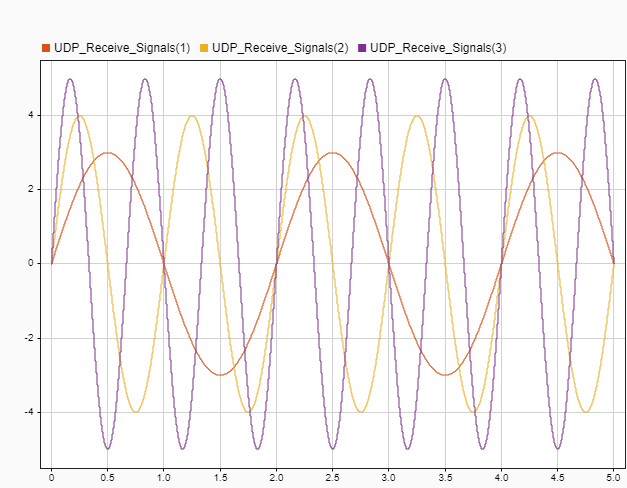

## Restore Target Configuration

To restore the default configuration, you can simply reopen the **Speedgoat Ethernet Configuration Tool** and tick the **Show Advanced Settings** checkbox. Then click the **Restore** button in the bottom right.

This will erase the IPs of every Ethernet interface and set the host link IP to 192.168.7.5 and the netmask to 255.255.255.0.

We recommend restoring the default settings to reduce possible configuration errors.

## Additional References

- [Real-Time UDP documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_realtime_udp)